This notebook is used to produce the different required plots for the kirigami parachute article.

## **Data loading section**

clear all; close all; clc;

%Adding path
path('./', path);

%Set font sizes
set(groot,'defaultAxesFontSize',12)

% This script undocks the figures. 
% list_factory = fieldnames(get(groot,'factory'));
% index_visible = find(contains(list_factory,'Visible'));
% for i = 1:length(index_visible)
%     default_name = strrep(list_factory{index_visible(i)},'factory','default');
%     set(groot, default_name,'on');
% end

% This script changes all interpreters from text to latex. 
list_factory = fieldnames(get(groot,'factory'));
index_interpreter = find(contains(list_factory,'Interpreter'));
for i = 1:length(index_interpreter)
    default_name = strrep(list_factory{index_interpreter(i)},'factory','default');
    set(groot, default_name,'latex');
end

dh = 0.516; %width difference in figures
dw = 0.19350; %height difference in figures

%Loading specimens definitions
excelSheet = "Experiments/AngularSpecimens/Specimens.xlsx";
defs = readtable(excelSheet, "sheet", "Definition");
temp = defs.Properties.VariableNames(2:end);
all_names = {};
for i = 1:length(temp)
    all_names{end+1} = temp{i};
end
defs = table2array(defs(:,2:end));

%Disk parameters
Rs = defs(1, :)*10^(-3);
Rc = defs(3, :)*10^(-3);
t = defs(4,:)*10^(-6);
tcut = 0.1E-3;
beta = Rs./Rc;
A = pi*(Rs.^2);% - Rc.^2);

%Material parameters
E = 4.91E9;
nu = 0.3;
B = E.*t.^3/(12*(1-nu^2));

%Flow parameters
rho = 1.225;

res = open("Experiments/AngularSpecimens/Rigid/UD.mat");
DR = res.D;
UR = res.U;

p = polyfit(UR, DR, 2);
CD0 = p(1)/(0.5*rho*A(1));

%CD0 = 1.1;
g = 9.81; %m/s

%Pattern parameters associated with specimens
drmin = defs(5,:)*10^(-3);
Ntheta = defs(6,:);
n = defs(7,:);
rtheta = defs(8,:);
Nr = defs(17,:);

%Unique parameters
ts = unique(t);
drmins = unique(drmin);
ns = unique(n);
Nthetas = unique(Ntheta);
rthetas = unique(rtheta);

%Properties
Kexp = defs(11, :);

%Unique colors
white = [1,1,1];
black = [0,0,0];
%green = [75, 204, 40]/256;
%blue = [10, 157, 255]/256;
red = [256,0,0]/256;
orange = [255, 201, 40]/256;
purple = [142, 76, 167]/256;
yellow = [249, 251, 21]/256;
grey = [142,156,165]/255;

green = sscanf("6CBA7D",'%2x%2x%2x',[1 3])/255;
blue = sscanf("6CB0D6",'%2x%2x%2x',[1 3])/255;

greenmap = @(len) [linspace(green(1), blue(1), len)', linspace(green(2), blue(2), len)', linspace(green(3), blue(3), len)'];
bluemap = [linspace(0, blue(1), 100), linspace(0, blue(2), 100), linspace(0, blue(3), 100)];
redmap = [linspace(0, red(1), 100), linspace(0, red(2), 100), linspace(0, red(3), 100)];

low = sscanf("40AD5A",'%2x%2x%2x',[1 3])/255;
mid = grey;
high = sscanf("3C93C2",'%2x%2x%2x',[1 3])/255;

sequentialmap = @(len) [linspace(low(1), high(1), len)', linspace(low(2), high(2), len)', linspace(low(3), high(3), len)'];

% colorst = greenmap(length(ts));
% colorsdr = greenmap(length(drmins));
% colorsn = greenmap(length(ns));
% colorsNtheta = greenmap(length(Nthetas));
% colorsrtheta = greenmap(length(rthetas));

% colorst = sequentialmap(length(ts));
% colorsdr = sequentialmap(length(drmins));
% colorsn = sequentialmap(length(ns));
% colorsNtheta = sequentialmap(length(Nthetas));
% colorsrtheta = sequentialmap(length(rthetas));

colorst = flipud(winter(length(ts)));
colorsdr = flipud(winter(length(drmins)));
colorsn = flipud(winter(length(ns)));
colorsNtheta = flipud(winter(length(Nthetas)));
colorsrtheta = flipud(winter(length(rthetas)));

%Reconfiguration
%Dimensional
% %AK8 non porous
% res = open("CorotationalReconfiguration/kirigami_disk/Specimens/AK8/AK8numreconfdim.mat");
% wsimK = res.ws;
% UsimK = res.Us;
% DsimK = res.Ds;
% 
% %AK8 Porous
% res = open("CorotationalReconfiguration/kirigami_disk/Specimens/AK8/AK8numreconfdimporous.mat");
% wsimKporous = res.ws;
% UsimKporous = res.Us;
% DsimKporous = res.Ds;
% 
% %AK10
% res = open("CorotationalReconfiguration/kirigami_disk/Specimens/AK10coarse/AK10numreconfdim.mat");
% wsimC = res.w;
% UsimC = res.U;
% DsimC = res.D;

%Adimensional
%AK8 non porous
res = open("CorotationalReconfiguration/kirigami_disk/Specimens/AK8/AK8numreconfadim.mat");
deltasimK = res.deltas;
CYsimK = res.CYs;
RsimK = res.Rs;

%AK8 Porous
res = open("CorotationalReconfiguration/kirigami_disk/Specimens/AK8/AK8numreconfadimporous.mat");
deltasimKporous = res.deltasGuttag;
CYsimKporous = res.CYsGuttag;
RsimKporous = res.RsGuttag;

%AK10
res = open("CorotationalReconfiguration/kirigami_disk/Specimens/AK10coarse/AK10numreconfadim.mat");
deltasimC = res.deltasC;
CYsimC = res.CYsC;
RsimC = res.RsC;

%Traction
%AK8
res = open("CorotationalReconfiguration/kirigami_disk/Specimens/AK8/AK8numtensile.mat");
forcesimK = res.fs;
dispsimK = res.ws;

%AK10
res = open("CorotationalReconfiguration/kirigami_disk/Specimens/AK10coarse/AK10numtensile.mat");
forcesimC = res.fs;
dispsimC = res.ws;

%Loading tensile data
path = "Experiments/AngularSpecimens/Tensile/";
list = dir(path);
disp = cell(1, length(all_names));
force = disp;
%Kexp = zeros(1, length(all_names));
for i = 1:length(list)
    item = list(i).name;
    if length(list(i).name(:)) > 2
        if list(i).name(end-3:end) == ".txt"
            name = item(1:end-4);
            if any(strcmpi(all_names,name))
                ind = find(strcmpi(all_names,name));
                data = table2array(readtable(path+item));
                index = 0;
                for j = 1:length(all_names)
                    if strcmpi(all_names{j}, item(1:end-4))
                        index = j;
                        break;
                    end
                end
                
                startforce = [];
                startdisp = [];
                newforce = [];
                newdisp = [];
                for j = 1:length(data(:,1))
                    if data(j,3) >= 5
                        startforce = -data(j:end, 2) + data(j,2);
                        startdisp = data(j:end,3) - data(j,3);
                        break
                    end
                end
                
                for j = 2:length(startdisp)
                    if startdisp(j) > startdisp(j-1)
                        newforce(end+1) = startforce(j);
                        newdisp(end+1) = startdisp(j);
                    else
                        break;
                    end
                end
                
                force(ind) = {newforce};
                disp(ind) = {newdisp/1000};
            elseif strcmpi("AK8_10cycles", name)
                data = table2array(readtable(path+item));
                
                for j = 1:length(data(:,1))
                    if data(j,3) >= 5
                        startforce = -data(j:end, 2) + data(j,2);
                        startdisp = (data(j:end,3) - data(j,3))/1000;
                        break
                    end
                end
                
                forward = true;
                dispstd = {}; forcestd = {};
                currentdisp = [startdisp(1)]; currentforce = [startforce(1)];
                for j = 2:length(startdisp)
                    currentdisp(end+1) = startdisp(j);
                    currentforce(end+1) = startforce(j);

                    if forward == true && startdisp(j-1) > startdisp(j)
                        [dispstd{end+1}, indices] = sort(currentdisp);
                        forcestd{end+1} = currentforce(indices);
                        currentdisp = [startdisp(j)];
                        currentforce = [startforce(j)];
                    elseif forward == false && startdisp(j-1) < startdisp(j)
                        [dispstd{end+1}, indices] = sort(currentdisp);
                        forcestd{end+1} = currentforce(indices);
                        currentdisp = [startdisp(j)];
                        currentforce = [startforce(j)];
                    end

                    if startdisp(j-1) <= startdisp(j)
                        forward = true;
                    else
                        forward = false;
                    end

                    
                end
                
                funcs = {};
                for j = 1:length(dispstd)-2
                    Md = movmean(dispstd{j}, 10);
                    Mf = movmean(forcestd{j}, 10);
                    funcs{end+1} = @(x) interp1(Md, Mf, x, "linear", "extrap");
                end

                meanvals = [];
                stdvals = [];

                minx = min(startdisp);
                maxx = max(startdisp);

                X = linspace(minx, maxx, 1000);

                for j = 1:length(X)
                    x = X(j);
                    vals = [];
                    for k = 1:length(funcs)
                        vals(end+1) = funcs{k}(x);
                    end
                    meanvals(end+1) = mean(vals);
                    stdvals(end+1) = std(vals);
                end

                
                
                curve1 = meanvals + 3*stdvals;
                curve2 = meanvals - 3*stdvals;

                f1 = figure();
                hold on;

                blue = [10, 157, 255]/256;

                p = fill([X, fliplr(X)]*1000, [curve1, fliplr(curve2)], blue,'FaceAlpha',0.3);
                p.EdgeColor = [1,1,1];
                plot(X*1000, meanvals, "-k", "linewidth", 2);

            end
        end
    end
end
axis tight;
xlabel("$w$ [mm]");
ylabel("$F$ [N]");

f1.Units = "centimeters";
f1.Position = [1 1 9.75 7];
figureSaver(f1, "bruteFigs/Hysteresis.pdf");


forcedisp = {};

for i = 1:length(disp)
    for j = 1:length(disp{i})
        forcedisp{j,2*(i-1)+1} = disp{i}(j);
        forcedisp{j,2*(i-1)+2} = force{i}(j);
    end
end


%Classifying specimens
modes = cell(1, length(all_names));
markers = cell(1, length(all_names));
colors = cell(1, length(all_names));
series = cell(1, length(all_names));
B = zeros(1, length(all_names));
Kbar = zeros(1, length(all_names));
ell = zeros(1, length(all_names));
epsKC = zeros(1, length(all_names));
lambdas = zeros(1, length(all_names));
porosity = zeros(1, length(all_names));
slitlengths = zeros(1, length(all_names));
Nrs = zeros(1, length(all_names));

Modes = readtable(excelSheet, "sheet", "Modes");

%Specimen loop
for j = 1:length(all_names)
    %Identifying the mode
    if strcmpi(Modes{1,j+2}, "C")
        modes{j} = "o";
    elseif strcmpi(Modes{1,j+2}, "K")
        modes{j} = "diamond";
    elseif strcmpi(Modes{1,j+2}, "K*")
        modes{j} = "square";
    elseif strcmpi(Modes{1,j+2}, "3K")
        modes{j} = "hexagram";
    end

    %Identify which series we are in
    cond1 = (Rs(j) == 70E-3);
    cond2 = (t(j) == 75E-6);
    cond3 = (drmin(j) == 2E-3);
    cond4 = (n(j) == 1);
    cond5 = (Ntheta(j) == 5);
    cond6 = (rtheta(j) == 0.3);
    
    if cond1 && cond2 && cond3 && cond4 && cond5 && cond6
        %basecase
        markers{j} = "o";
        colors{j} = [0,0,0];
        series{j} = "base";
    elseif cond1 && cond6 && cond3 && cond4 && cond5
        %t
        ind = find(t(j) == ts);
        markers{j} = "pentagram";
        colors{j} = colorst(ind,:);
        series{j} = "t";
    elseif cond1 && cond2 && cond6 && cond4 && cond5
        %dr
        ind = find(drmin(j) == drmins);
        markers{j} = "square";
        colors{j} = colorsdr(ind,:);
        series{j} = "dr";
    elseif cond1 && cond2 && cond3 && cond6 && cond5
        %n
        ind = find(n(j) == ns);
        markers{j} = "diamond";
        colors{j} = colorsn(ind,:);
        series{j} = "n";
    elseif cond1 && cond2 && cond3 && cond4 && cond6
        %Ntheta
        ind = find(Ntheta(j) == Nthetas);
        markers{j} = "hexagram";
        colors{j} = colorsNtheta(ind,:);
        series{j} = "Ntheta";
    elseif cond1 && cond2 && cond3 && cond4 && cond5
        %rtheta
        ind = find(rtheta(j) == rthetas);
        markers{j} = "^";
        colors{j} = colorsrtheta(ind,:);
        series{j} = "rtheta";
    end

    %Calculating properties
    [Kbari, elli, epsKCi, lambdai, slitLengthi, Nri] = getKirigamiValues(Rs(j), Rc(j), 1.35E-3, drmin(j)./Rs(j), n(j), Ntheta(j), rtheta(j));
    porosity(j) = slitLengthi*tcut/A(j);
    Kbar(j) = Kbari; ell(j) = elli; epsKC(j) = epsKCi; B(j) = E*t(j)^3/12;
    lambdas(j) = lambdai; slitlengths(j) = slitLengthi; Nrs(j) = Nri;
end

## **Tensile tests section**

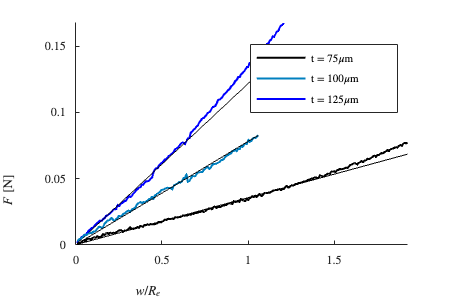

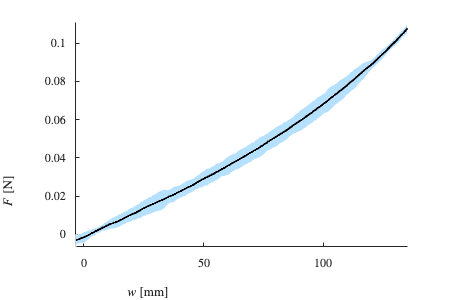


%Plotting force-extension plots
f1 = figure("Name", "Tensile t", 'Position', [50 150 450 300]); %Tensile t
hold on;
xlabel("$w/R_e$");
ylabel("$F$ [N]");
f2 = figure("Name", "Tensile dr", 'Position', [50 150 450 300]); %Tensile dr
hold on;
xlabel("$w/R_e$");
ylabel("$F$ [N]");
f3 = figure("Name", "Tensile n", 'Position', [50 150 450 300]); %Tensile n
hold on;
xlabel("$w/R_e$");
ylabel("$F$ [N]");
f4 = figure("Name", "Tensile Ntheta", 'Position', [50 150 450 300]); %Tensile Ntheta
hold on;
xlabel("$w/R_e$");
ylabel("$F$ [N]");
f5 = figure("Name", "Tensile rtheta", 'Position', [50 150 450 300]); %Tensile rtheta
hold on;
xlabel("$w/R_e$");
ylabel("$F$ [N]");

torder = []; tplots = gobjects(length(ts), 1);
drorder = [];drplots = gobjects(length(drmins), 1);
norder = []; nplots = gobjects(length(ns), 1);
Nthetaorder = []; Nthetaplots = gobjects(length(Nthetas), 1);
rthetaorder = []; rthetaplots = gobjects(length(rthetas), 1);

for j = 1:length(all_names)
    switch series{j}
        case "base"
            for i = 1:5
                switch i
                    case 1
                        figure(f1);
                        ind = find(t(j) == ts);
                        tplots(ind) = plot(disp{j}/Rs(j), force{j}, "color", colors{j}, 'linewidth', 2, "DisplayName", "t = "+num2str(t(j)*10^6)+"$\mu$m");
                        torder(end+1) = ind;
                        plot(disp{j}/Rs(j), Kexp(j)*disp{j}, "-k", "linewidth", 0.5);
                    case 2
                        figure(f2);
                        ind = find(drmin(j) == drmins);
                        drplots(ind) = plot(disp{j}/Rs(j), force{j}, "color", colors{j}, 'linewidth', 2, "DisplayName", "$\Delta r_2 = $"+num2str(drmin(j)*10^3)+"mm");
                        
                        drorder(end+1) = ind;
                        plot(disp{j}/Rs(j), Kexp(j)*disp{j}, "-k", "linewidth", 0.5);
                    case 3
                        figure(f3);
                        ind = find(n(j) == ns);
                        nplots(ind) = plot(disp{j}/Rs(j), force{j}, "color", colors{j}, 'linewidth', 2, "DisplayName", "$n = $"+num2str(n(j)));
                        
                        norder(end+1) = ind;
                        plot(disp{j}/Rs(j), Kexp(j)*disp{j}, "-k", "linewidth", 0.5);
                    case 4
                        figure(f4);
                        ind = find(Ntheta(j) == Nthetas);
                        Nthetaplots(ind) = plot(disp{j}/Rs(j), force{j}, "color", colors{j}, 'linewidth', 2, "DisplayName", "$N_\theta = $"+num2str(Ntheta(j)));
                        
                        Nthetaorder(end+1) = ind;
                        plot(disp{j}/Rs(j), Kexp(j)*disp{j}, "-k", "linewidth", 0.5);
                    case 5
                        figure(f5);
                        ind = find(rtheta(j) == rthetas);
                        rthetaplots(ind) = plot(disp{j}/Rs(j), force{j}, "color", colors{j}, 'linewidth', 2, "DisplayName", "$\Theta = $"+num2str(rtheta(j)));
                        
                        rthetaorder(end+1) = ind;
                        plot(disp{j}/Rs(j), Kexp(j)*disp{j}, "-k", "linewidth", 0.5);
                end
            end
        case "t"
            figure(f1);
            ind = find(t(j) == ts);
            tplots(ind) = plot(disp{j}/Rs(j), force{j}, "color", colors{j}, 'linewidth', 2, 'DisplayName', "t = "+num2str(t(j)*10^6)+"$\mu$m");
            
            torder(end+1) = ind;
            plot(disp{j}/Rs(j), Kexp(j)*disp{j}, "-k", "linewidth", 0.5);
        case "dr"
            figure(f2);
            ind = find(drmin(j) == drmins);
            drplots(ind) = plot(disp{j}/Rs(j), force{j}, "color", colors{j}, 'linewidth', 2, 'DisplayName', "$\Delta r_2 = $"+num2str(drmin(j)*10^3)+"mm");
            
            drorder(end+1) = ind;
            plot(disp{j}/Rs(j), Kexp(j)*disp{j}, "-k", "linewidth", 0.5);
        case "n"
            figure(f3);
            ind = find(n(j) == ns);
            nplots(ind) = plot(disp{j}/Rs(j), force{j}, "color", colors{j}, 'linewidth', 2, 'DisplayName', "$n = $"+num2str(n(j)));
            
            norder(end+1) = ind;
            plot(disp{j}/Rs(j), Kexp(j)*disp{j}, "-k", "linewidth", 0.5);
        case "Ntheta"
            figure(f4);
            ind = find(Ntheta(j) == Nthetas);
            Nthetaplots(ind) = plot(disp{j}/Rs(j), force{j}, "color", colors{j}, 'linewidth', 2, 'DisplayName', "$N_\theta = $"+num2str(Ntheta(j)));
            
            Nthetaorder(end+1) = ind;
            plot(disp{j}/Rs(j), Kexp(j)*disp{j}, "-k", "linewidth", 0.5);
        case "rtheta"
            figure(f5);
            ind = find(rtheta(j) == rthetas);
            rthetaplots(ind) = plot(disp{j}/Rs(j), force{j}, "color", colors{j}, 'linewidth', 2, 'DisplayName', "$\Theta = $"+num2str(rtheta(j)));
            
            rthetaorder(end+1) = ind;
            plot(disp{j}/Rs(j), Kexp(j)*disp{j}, "-k", "linewidth", 0.5);
    end
end

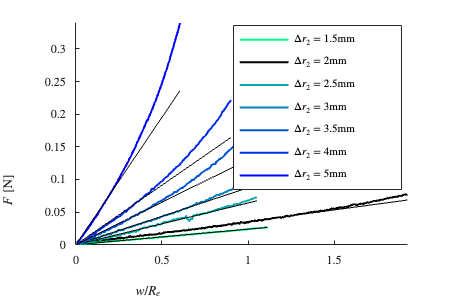

%Reorder legends and correct limits
for i = 1:5
    xlim([0, inf]);
    ylim([0, inf]);
    switch i
        case 1
            figure(f1);
            legend(tplots, "Location", "best");
            f1.Units = "centimeters";
            f1.Position = [1 1 9.75 7];
            f1.Units = "points";
            figureSaver(f1, "bruteFigs/tensilet.pdf");
        case 2
            figure(f2);
            legend(drplots, "Location", "best");
            f2.Units = "centimeters";
            f2.Position = [1 1 9.75 7];
            f2.Units = "points";
            figureSaver(f2, "bruteFigs/tensiledr.pdf");
        case 3
            figure(f3);
            legend(nplots, "Location", "best");
            f3.Units = "centimeters";
            f3.Position = [1 1 9.75 7];
            f3.Units = "points";
            figureSaver(f3, "bruteFigs/tensilen.pdf");
        case 4
            figure(f4);
            legend(Nthetaplots, "Location", "best");
            f4.Units = "centimeters";
            f4.Position = [1 1 9.75 7];
            f4.Units = "points";
            figureSaver(f4, "bruteFigs/tensileNtheta.pdf");
        case 5
            figure(f5);
            legend(rthetaplots, "Location", "best");
            f5.Units = "centimeters";
            f5.Position = [1 1 9.75 7];
            f5.Units = "points";
            figureSaver(f5, "bruteFigs/tensilertheta.pdf");
    end
end

%Comparison experimental stiffness - stiffness model
f12 = figure("Name", "StiffComp", 'Position', [50 150 450 300]);
hold on;
ylabel("$K$ [N/m]");
xlabel("$\tilde{K}=B\bar{K}/R_e^2$ [N/m]");
Ktheo = Kbar.*B./Rs.^2;
for j = 1:length(all_names)
    scatter(Ktheo(j), Kexp(j), "marker", markers{j}, "MarkerFaceColor", colors{j}, "MarkerEdgeColor", colors{j});
end
set(gca, 'XScale', 'log')
set(gca, 'YScale', 'log')
axis("tight");
p = polyfit(log10(Ktheo), log10(Kexp), 1);
pK = p;
fprintf("Order of the fit = "+num2str(p(1))+" which means Ktheo scales with K");
x = [min(Ktheo), max(Ktheo)];
plot(x, 10.^polyval(p, log10(x)), "-k");
f12.Units = "centimeters";
f12.Position = [1 1 9.75 7];
f12.Units = "points";
figureSaver(f12, "bruteFigs/stiffComp.pdf");

%Experimental Kbar vs ell
f1 = figure("Name", "KvEll");
hold on;
ylabel("$\bar{K}$");
xlabel("$\ell$")

orderedE = sort(epsKC);
colorsE = flipud(winter(length(orderedE)));


for j = 1:length(all_names)
    ind = find(epsKC(j) == orderedE);
    ind = ind(1);
    scatter(ell(j), Kbar(j), "marker", markers{j}, "MarkerFaceColor", colorsE(ind,:), "MarkerEdgeColor", colorsE(ind,:));
end
axis("tight");
x = linspace(1, 8, 100);
y = 28./x;
plot(x,y, '-k');
%set(gca, 'XScale', 'log')
%set(gca, 'YScale', 'log')


%Phase diagram
f1 = figure("Name", "Transition");
hold on;
xlabel("$\bar{K}$");
ylabel("$\varepsilon_K/\varepsilon_C$")
for j = 1:length(all_names)
    scatter(Kbar(j), epsKC(j), "marker", modes{j}, "MarkerFaceColor", colors{j}, "MarkerEdgeColor", colors{j});
end
axis("tight");
xs = xlim();
ys = ylim();
plot(xs, [9,9]/10^6, "-k", "linewidth", 2);
plot([28, 28], ys, "--", "color", blue, "linewidth", 2);
xlim([xs(1)*0.9, xs(2)*1.1]); ylim([ys(1)*0.9, ys(2)*1.1]);
set(gca, 'XScale', 'log')
set(gca, 'YScale', 'log')
axis("tight");
f1.Units = "centimeters";
f1.Position = [1 1 9.75, 7];
figureSaver(f1, "bruteFigs/transition.pdf");

%Stiffness according to slit length or number of cuts
%Phase diagram
f1 = figure("Name", "Transition");
hold on;
ylabel("$\bar{K}$");
xlabel("$Slit length$")
for j = 1:length(all_names)
    scatter(slitlengths(j), Kbar(j), "marker", modes{j}, "MarkerFaceColor", colors{j}, "MarkerEdgeColor", colors{j});
end
axis("tight");
xs = xlim();
ys = ylim();
%plot(xs, [9,9]/10^6, "-k", "linewidth", 2);
plot(xs, [28, 28], "--", "color", blue, "linewidth", 2);
xlim([xs(1)*0.9, xs(2)*1.1]); ylim([ys(1)*0.9, ys(2)*1.1]);
set(gca, 'XScale', 'log')
set(gca, 'YScale', 'log')
axis("tight");
f1.Units = "centimeters";
f1.Position = [1 1 9.75, 7];
figureSaver(f1, "bruteFigs/transition.pdf");

%Bar graph
f1 = figure("Name", "Transition");
hold on;
ylabel("$\bar{K}$");
xlabel("Specimen number (Arbitrary)");
x = 1:1:length(Kbar);
b = bar(x, Kbar);
b.FaceColor = 'flat';
for j = 1:length(Kbar)
    if modes{j} == "diamond"
        b.CData(j,:) = green;
    elseif modes{j} == "o"
        b.CData(j,:) = blue;
    end
end
axis("tight");
xs = xlim();
ylim([0, 200]);
plot(xs, [28, 28], "--", "color", blue, "linewidth", 2);
xlim([xs(1)*0.9, xs(2)*1.1]); ylim([ys(1)*0.9, ys(2)*1.1]);
%set(gca, 'XScale', 'log')
%set(gca, 'YScale', 'log')
%axis("tight");
f1.Units = "centimeters";
f1.Position = [1 1 9.75, 7];
figureSaver(f1, "bruteFigs/transition.pdf");

%Comparing dimensional tensile tests to numerical and semi-analytical
%results

f1 = figure("Name", "TensileCompModels", 'Position', [50 150 450 300]);
hold on;
xlabel("$w$ [m]");
ylabel("$F$ [N]");

h = gobjects(4,1);

%AK8
%Exp
h(1) = plot(disp{1}, force{1}, "color", green, 'linewidth', 2, 'DisplayName', "Experimental");

%plot(disp{1}, disp{1}*Kexp(1), "-k", "linewidth", 0.5);

%FEM
for i = 20:length(dispsimK)
    mdl = fitlm(dispsimK(5:i), forcesimK(5:i));
    r2 = mdl.Rsquared.Ordinary;
    if r2 < 0.9999
        diff = i - 1;
        break;
    end
    if i == length(dispsimK)
        diff = i;
    end
end

linforce = forcesimK(5:diff-1);
lindisp = dispsimK(5:diff-1);
p = polyfit(lindisp, linforce, 1);
KsimK = p(1);

plot(dispsimK, forcesimK, "--", "color", green, 'linewidth', 2, 'DisplayName', "FEM")
%plot(dispsimK, KsimK*dispsimK, '-k', "linewidth", 0.5);

%Computing dimensional values - nonporous
UsimK = sqrt(CYsimK*KsimK*ell(1)/(rho*Rs(1)*CD0));
DsimK = RsimK.*0.5.*rho.*UsimK.^2.*A(1).*CD0;
wsimK = deltasimK*ell(1)*Rs(1);

%Computing dimensional values - porous
UsimKporous = sqrt(CYsimKporous*KsimK*ell(1)/(rho*Rs(1)*CD0));
DsimKporous = RsimKporous.*0.5.*rho.*UsimKporous.^2.*A(1).*CD0;
wsimKporous = deltasimKporous*ell(1)*Rs(1);

%AK10
%Exp
h(3) = plot(disp{3}, force{3}, "color", blue, 'linewidth', 2, 'DisplayName', "Experimental");
x = linspace(min(disp{3}), max(disp{3}), 2);
y = Kexp(3)*x;
%plot(x,y, "-k");

%FEM
for i = 20:length(dispsimC)
    mdl = fitlm(dispsimC(5:i), forcesimC(5:i));
    r2 = mdl.Rsquared.Ordinary;
    if r2 < 0.9999
        diff = i - 1;
        break;
    end
    if i == length(dispsimK)
        diff = i;
    end
end

linforce = forcesimC(5:diff-1);
lindisp = dispsimC(5:diff-1);
p = polyfit(lindisp, linforce, 1);
KsimC = p(1);

plot(dispsimC, forcesimC, "--", "color", blue, 'linewidth', 2, 'DisplayName', "FEM")
%plot(dispsimC, KsimC*dispsimC, '-k', "linewidth", 0.5);

%Computing dimensional values
UsimC = sqrt(CYsimC*B(3)*log(Rs(3)/Rc(3))/(rho*CD0*Rs(3)^3));
DsimC = RsimC.*0.5.*rho.*UsimC.^2.*A(3).*CD0;
wsimC = deltasimC*Rs(3);

%legend(h, "location", "best");
%legend("Experimental", "FEM");
%axis("tight");
axis tight;
xlim([0, 0.15]);
ylim([0, 0.1]);
f1.Units = "centimeters";
%f1.Position = [1 1 8 6];
f1.Position = [1 1 15 10];
f1.Units = "points";
figureSaver(f1, "bruteFigs/TensileCompModels.pdf");

%Dimensionless tensile test
f11 = figure("Name", "Dimensionless Tensile", 'Position', [50 150 450 300]);
hold on;
%xlabel("$w [m]$")
%ylabel("$F [N]$")
xlabel("$\delta = \frac{w}{r_o\ell}$")
ylabel("$\mathcal{F} = F/(Kr_o\ell)$")
for j = 1:length(all_names)
    Fmax = Kexp(j)*Rs(j)*ell(j);
    switch series{j}
        case "base"
            line = ":";
            width = 3;
        case "t"
            line = ":";
            width = 0.5;
        case "dr"
            line = ":";
            width = 2;
        case "n"
            line = ":";
            width = 1;
        case "Ntheta"
            line = ":";
            width = 1.5;
        case "rtheta"
            line = ":";
            width = 2.5;
    end
    plot(disp{j}/(Rs(j)*ell(j)), force{j}/(Kexp(j)*Rs(j)*ell(j)), "color", colors{j}, "linestyle", line, "linewidth", width);
end

%Tensile theoretical model (linear and nonlinear)
h = gobjects(1,1);

h(1) = plot(dispsimK/(Rs(1)*ell(1)), forcesimK/(KsimK*Rs(1)*ell(1)), "--b", "linewidth", 1, "DisplayName", "FEM - Design B");
% h(2) = plot(dispsimC/(Rs(3)*ell(3)), forcesimC/(KsimC*Rs(3)*ell(3)), "--r", "linewidth", 1, "DisplayName", "FEM - Design A");
axis("tight");
%legend(h, "location", "best");
figureSaver(f11, "bruteFigs/dimensionlessTensileComp.pdf");

## Wind tunnel extension section

%Windtunnel data from Montreal
velocity = cell(1, length(all_names));
drag = cell(1, length(all_names));
extension = cell(1, length(all_names));

cd Experiments/AngularSpecimens/;

folders = dir();
for i = 3:length(folders)
    if isfolder(folders(i).name) && ~strcmpi(folders(i).name, "Rigid") ...
            && ~strcmpi(folders(i).name, "Empty") && ~strcmpi(folders(i).name, "Assembled") ...
            && ~strcmpi(folders(i).name, "drawings") && ~strcmpi(folders(i).name, "Obsolete") ...
            && ~strcmpi(folders(i).name, "Tensile") && ~strcmpi(folders(i).name, "AngleAK8") && ~strcmpi(folders(i).name, "AngleEmpty")
        load(folders(i).name+"/UDL.mat");
        for j = 1:length(all_names)
            if strcmpi(folders(i).name, all_names{j})
                break;
            end
        end
        velocity{j} = U;
        drag{j} = D;
        extension{j} = L;
        
        if strcmpi(folders(i).name, "AK10")
            modes{j} = "o";
        else
            modes{j} = "diamond";
        end
    end
end

cd ../..;

%Plotting the displacement of each series under flow
f6 = figure("Name", "Disp t", 'Position', [50 150 450 300]); %Tensile t
hold on;
xlabel("$U$ [m/s]");
ylabel("$w$ [m]");
f7 = figure("Name", "Disp dr", 'Position', [50 150 450 300]); %Tensile dr
hold on;
xlabel("$U$ [m/s]");
ylabel("$w$ [m]");
f8 = figure("Name", "Disp n", 'Position', [50 150 450 300]); %Tensile n
hold on;
xlabel("$U$ [m/s]");
ylabel("$w$ [m]");
f9 = figure("Name", "Disp Ntheta", 'Position', [50 150 450 300]); %Tensile Ntheta
hold on;
xlabel("$U$ [m/s]");
ylabel("$w$ [m]");
f10 = figure("Name", "Disp rtheta", 'Position', [50 150 450 300]); %Tensile rtheta
hold on;
xlabel("$U$ [m/s]");
ylabel("$w$ [m]");

ts = [75, 125]*10^(-6);
drmins = [2, 2.5, 3]*10^(-3);
ns = [1, 1.025];
Nthetas = [4, 5, 8];
rthetas = [0.2, 0.3, 0.35, 0.4];

torder = []; tplots = gobjects(length(ts), 1);
drorder = [];drplots = gobjects(length(drmins), 1);
norder = []; nplots = gobjects(length(ns), 1);
Nthetaorder = []; Nthetaplots = gobjects(length(Nthetas), 1);
rthetaorder = []; rthetaplots = gobjects(length(rthetas), 1);

for j = 1:length(all_names)
    if ~isempty(velocity{j})
    switch series{j}
        case "base"
            for i = 1:5
                switch i
                    case 1
                        figure(f6);
                        ind = find(t(j) == ts);
                        tplots(ind) = plot(velocity{j}, extension{j}, "color", colors{j}, "DisplayName", "t = "+num2str(t(j)*10^6)+"$\mu$m");
                        torder(end+1) = ind;
                        for k = 1:length(velocity{j})
                            scatter(velocity{j}(k), extension{j}(k), "MarkerEdgeColor", colors{j}, "MarkerFaceColor", colors{j}, "marker", modes{j});
                        end
                    case 2
                        figure(f7);
                        ind = find(drmin(j) == drmins);
                        drplots(ind) = plot(velocity{j}, extension{j}, "color", colors{j}, "DisplayName", "$\Delta r_2 = $"+num2str(drmin(j)*10^3)+"mm");
                        
                        drorder(end+1) = ind;
                        for k = 1:length(velocity{j})
                            scatter(velocity{j}(k), extension{j}(k), "MarkerEdgeColor", colors{j}, "MarkerFaceColor", colors{j}, "marker", modes{j})
                        end
                    case 3
                        figure(f8);
                        ind = find(n(j) == ns);
                        nplots(ind) = plot(velocity{j}, extension{j}, "color", colors{j}, "DisplayName", "$n = $"+num2str(n(j)));
                        
                        norder(end+1) = ind;
                        for k = 1:length(velocity{j})
                            scatter(velocity{j}(k), extension{j}(k), "MarkerEdgeColor", colors{j}, "MarkerFaceColor", colors{j}, "marker", modes{j})
                        end
                    case 4
                        figure(f9);
                        ind = find(Ntheta(j) == Nthetas);
                        Nthetaplots(ind) = plot(velocity{j}, extension{j}, "color", colors{j}, "DisplayName", "$N_\theta = $"+num2str(Ntheta(j)));
                        
                        Nthetaorder(end+1) = ind;
                        for k = 1:length(velocity{j})
                            scatter(velocity{j}(k), extension{j}(k), "MarkerEdgeColor", colors{j}, "MarkerFaceColor", colors{j}, "marker", modes{j})
                        end
                    case 5
                        figure(f10);
                        ind = find(rtheta(j) == rthetas);
                        rthetaplots(ind) = plot(velocity{j}, extension{j}, "color", colors{j}, "DisplayName", "$\Theta = $"+num2str(rtheta(j)));
                        
                        rthetaorder(end+1) = ind;
                        for k = 1:length(velocity{j})
                            scatter(velocity{j}(k), extension{j}(k), "MarkerEdgeColor", colors{j}, "MarkerFaceColor", colors{j}, "marker", modes{j})
                        end
                end
            end
        case "t"
            figure(f6);
            ind = find(t(j) == ts);
            tplots(ind) = plot(velocity{j}, extension{j}, "color", colors{j}, 'DisplayName', "t = "+num2str(t(j)*10^6)+"$\mu$m");
            
            torder(end+1) = ind;
            for k = 1:length(velocity{j})
                scatter(velocity{j}(k), extension{j}(k), "MarkerEdgeColor", colors{j}, "MarkerFaceColor", colors{j}, "marker", modes{j})
            end
        case "dr"
            figure(f7);
            ind = find(drmin(j) == drmins);
            drplots(ind) = plot(velocity{j}, extension{j}, "color", colors{j}, 'DisplayName', "$\Delta r_2 = $"+num2str(drmin(j)*10^3)+"mm");
            
            drorder(end+1) = ind;
            for k = 1:length(velocity{j})
                scatter(velocity{j}(k), extension{j}(k), "MarkerEdgeColor", colors{j}, "MarkerFaceColor", colors{j}, "marker", modes{j})
            end
        case "n"
            figure(f8);
            ind = find(n(j) == ns);
            nplots(ind) = plot(velocity{j}, extension{j}, "color", colors{j}, 'DisplayName', "$n = $"+num2str(n(j)));
            
            norder(end+1) = ind;
            for k = 1:length(velocity{j})
                scatter(velocity{j}(k), extension{j}(k), "MarkerEdgeColor", colors{j}, "MarkerFaceColor", colors{j}, "marker", modes{j})
            end
        case "Ntheta"
            figure(f9);
            ind = find(Ntheta(j) == Nthetas);
            Nthetaplots(ind) = plot(velocity{j}, extension{j}, "color", colors{j}, 'DisplayName', "$N_\theta = $"+num2str(Ntheta(j)));
            
            Nthetaorder(end+1) = ind;
            for k = 1:length(velocity{j})
                scatter(velocity{j}(k), extension{j}(k), "MarkerEdgeColor", colors{j}, "MarkerFaceColor", colors{j}, "marker", modes{j})
            end
        case "rtheta"
            figure(f10);
            ind = find(rtheta(j) == rthetas);
            rthetaplots(ind) = plot(velocity{j}, extension{j}, "color", colors{j}, 'DisplayName', "$\Theta = $"+num2str(rtheta(j)));
            
            rthetaorder(end+1) = ind;
            for k = 1:length(velocity{j})
                scatter(velocity{j}(k), extension{j}(k), "MarkerEdgeColor", colors{j}, "MarkerFaceColor", colors{j}, "marker", modes{j})
            end
    end
    end
end
%Reorder legends
for i = 1:5
    switch i
        case 1
            figure(f6);
            legend(tplots, "Location", "best");
            f6.Units = "centimeters";
            f6.Position = [1 1 9.75 7];
            f6.Units = "points";
            figureSaver(f6, "bruteFigs/dispt.pdf");
        case 2
            figure(f7);
            legend(drplots, "Location", "best");
            f7.Units = "centimeters";
            f7.Position = [1 1 9.75 7];
            f7.Units = "points";
            figureSaver(f7, "bruteFigs/dispdr.pdf");
        case 3
            figure(f8);
            legend(nplots, "Location", "best");
            f8.Units = "centimeters";
            f8.Position = [1 1 9.75 7];
            f8.Units = "points";
            figureSaver(f8, "bruteFigs/dispn.pdf");
        case 4
            figure(f9);
            legend(Nthetaplots, "Location", "best");
            f9.Units = "centimeters";
            f9.Position = [1 1 9.75 7];
            f9.Units = "points";
            figureSaver(f9, "bruteFigs/dispNtheta.pdf");
        case 5
            figure(f10);
            legend(rthetaplots, "Location", "best");
            f10.Units = "centimeters";
            f10.Position = [1 1 9.75 7];
            f10.Units = "points";
            figureSaver(f10, "bruteFigs/disprtheta.pdf");
    end
end

%Comparing dimensional drag results tests to numerical and semi-analytical
%results

f1 = figure("Name", "DragCompModels", 'Position', [50 150 450 300]);
hold on;
xlabel("$U_\infty$ [m/s]");
ylabel("$w$ [m]");

h = gobjects(4,1);

%AK8
%Exp
h(1) = plot(velocity{1}, extension{1}, "-diamond", "color", green, "MarkerFaceColor", green, 'linewidth', 2, 'DisplayName', "Experimental");

%FEM
h(2) = plot(UsimKporous, wsimKporous, ":", "color", green, "linewidth", 2, "DisplayName", "FIRM");

%AK10
%Exp
h(3) = plot(velocity{3}, extension{3}, "-o", "color", blue, "MarkerFaceColor", blue, 'linewidth', 2, 'DisplayName', "Experimental");

%FEM
h(4) = plot(UsimC, wsimC, ":", "color", blue, "linewidth", 2, "DisplayName", "FIRM");

xticks([0,1,2,3,4,5])
%legend(h, "location", "best");
%axis("tight");
xlim([0, 5]);
ylim([0, 0.12]);
f1.Units = "centimeters";
f1.Position = [1 1 6.3 5.5];
f1.Units = "points";
figureSaver(f1, "bruteFigs/DispCompModels.pdf");

%Dimensionless displacement
f1 = figure("Name", "Dimensionless displacement", 'Position', [50 150 450 300]);
hold on;
xlabel("$C_Y = \frac{\rho U_\infty^2 C_DR_e}{K\ell}$")
ylabel("$\delta = \frac{w}{R_e\ell}$")

allx = [];
ally = [];

for j = 1:length(all_names)
    currentx = [];
    currenty = [];
    for i = 2:length(velocity{j})
        if strcmpi(modes{j}, "diamond")
            CYCD = CD0*(rho*velocity{j}(i)^2*Rs(j))/(Kexp(j)*ell(j));
        currentx(end+1) = CYCD;
        currenty(end+1) = extension{j}(i)/(Rs(j)*ell(j));% - Rc(j));
        allx(end+1) = currentx(end);
        ally(end+1) = currenty(end);
        end
    end
    
    plot(currentx, currenty, "color", colors{j});
    scatter(currentx, currenty, "marker", markers{j}, "MarkerFaceColor", colors{j}, "MarkerEdgeColor", colors{j}, "LineWidth", 0.1);
end

save("ExtensionExp.mat", "allx", "ally");

h = gobjects(2,1);

h(1) = plot(CYsimK, deltasimK, "-k", "DisplayName", "FIRM");
h(1) = plot(CYsimKporous, deltasimKporous, "--k", "DisplayName", "FIRM Porous");

deltasimKModel = @(CY) interp1(CYsimKporous, deltasimKporous, CY);
%deltasimKModel = @(CY) interp1(CYsimK, deltasimK, CY);
%legend(h, "Location", "best");

set(gca, 'XScale', 'log')
%set(gca, 'YScale', 'log')
xlim([10^(-3),10])
f1.Units = "centimeters";
f1.Position = [1 1 9.2, 6.8];
figureSaver(f1, "bruteFigs/dimensionlessdisp.pdf");

## **Windtunnel drag section**

%Plotting the drag of each series under flow
f6 = figure("Name", "Drag t", 'Position', [50 150 450 300]); %Tensile t
hold on;
xlabel("$U$ [m/s]");
ylabel("$D$ [N]");
f7 = figure("Name", "Drag dr", 'Position', [50 150 450 300]); %Tensile dr
hold on;
xlabel("$U$ [m/s]");
ylabel("$D$ [N]");
f8 = figure("Name", "Drag n", 'Position', [50 150 450 300]); %Tensile n
hold on;
xlabel("$U$ [m/s]");
ylabel("$D$ [N]");
f9 = figure("Name", "Drag Ntheta", 'Position', [50 150 450 300]); %Tensile Ntheta
hold on;
xlabel("$U$ [m/s]");
ylabel("$D$ [N]");
f10 = figure("Name", "Drag rtheta", 'Position', [50 150 450 300]); %Tensile rtheta
hold on;
xlabel("$U$ [m/s]");
ylabel("$D$ [N]");

ts = [75, 125]*10^(-6);
drmins = [2, 2.5, 3]*10^(-3);
ns = [1, 1.025];
Nthetas = [4, 5, 8];
rthetas = [0.2, 0.3, 0.35, 0.4];

torder = []; tplots = gobjects(length(ts), 1);
drorder = [];drplots = gobjects(length(drmins), 1);
norder = []; nplots = gobjects(length(ns), 1);
Nthetaorder = []; Nthetaplots = gobjects(length(Nthetas), 1);
rthetaorder = []; rthetaplots = gobjects(length(rthetas), 1);

ntested = 0;
testedKs = [];
for j = 1:length(all_names)
    if ~isempty(velocity{j})
        ntested = ntested + 1;
        testedKs(end+1) = Kexp(j);
    switch series{j}
        case "base"
            for i = 1:5
                switch i
                    case 1
                        figure(f6);
                        ind = find(t(j) == ts);
                        tplots(ind) = plot(velocity{j}, drag{j}, "color", colors{j}, "DisplayName", "t = "+num2str(t(j)*10^6)+"$\mu$m");
                        torder(end+1) = ind;
                        for k = 1:length(velocity{j})
                            scatter(velocity{j}(k), drag{j}(k), "MarkerEdgeColor", colors{j}, "MarkerFaceColor", colors{j}, "marker", modes{j});
                        end
                    case 2
                        figure(f7);
                        ind = find(drmin(j) == drmins);
                        drplots(ind) = plot(velocity{j}, drag{j}, "color", colors{j}, "DisplayName", "$\Delta r_2 = $"+num2str(drmin(j)*10^3)+"mm");
                        
                        drorder(end+1) = ind;
                        for k = 1:length(velocity{j})
                            scatter(velocity{j}(k), drag{j}(k), "MarkerEdgeColor", colors{j}, "MarkerFaceColor", colors{j}, "marker", modes{j})
                        end
                    case 3
                        figure(f8);
                        ind = find(n(j) == ns);
                        nplots(ind) = plot(velocity{j}, drag{j}, "color", colors{j}, "DisplayName", "$n = $"+num2str(n(j)));
                        
                        norder(end+1) = ind;
                        for k = 1:length(velocity{j})
                            scatter(velocity{j}(k), drag{j}(k), "MarkerEdgeColor", colors{j}, "MarkerFaceColor", colors{j}, "marker", modes{j})
                        end
                    case 4
                        figure(f9);
                        ind = find(Ntheta(j) == Nthetas);
                        Nthetaplots(ind) = plot(velocity{j}, drag{j}, "color", colors{j}, "DisplayName", "$N_\theta = $"+num2str(Ntheta(j)));
                        
                        Nthetaorder(end+1) = ind;
                        for k = 1:length(velocity{j})
                            scatter(velocity{j}(k), drag{j}(k), "MarkerEdgeColor", colors{j}, "MarkerFaceColor", colors{j}, "marker", modes{j})
                        end
                    case 5
                        figure(f10);
                        ind = find(rtheta(j) == rthetas);
                        rthetaplots(ind) = plot(velocity{j}, drag{j}, "color", colors{j}, "DisplayName", "$\Theta = $"+num2str(rtheta(j)));
                        
                        rthetaorder(end+1) = ind;
                        for k = 1:length(velocity{j})
                            scatter(velocity{j}(k), drag{j}(k), "MarkerEdgeColor", colors{j}, "MarkerFaceColor", colors{j}, "marker", modes{j})
                        end
                end
            end
        case "t"
            figure(f6);
            ind = find(t(j) == ts);
            tplots(ind) = plot(velocity{j}, drag{j}, "color", colors{j}, 'DisplayName', "t = "+num2str(t(j)*10^6)+"$\mu$m");
            
            torder(end+1) = ind;
            for k = 1:length(velocity{j})
                scatter(velocity{j}(k), drag{j}(k), "MarkerEdgeColor", colors{j}, "MarkerFaceColor", colors{j}, "marker", modes{j})
            end
        case "dr"
            figure(f7);
            ind = find(drmin(j) == drmins);
            drplots(ind) = plot(velocity{j}, drag{j}, "color", colors{j}, 'DisplayName', "$\Delta r_2 = $"+num2str(drmin(j)*10^3)+"mm");
            
            drorder(end+1) = ind;
            for k = 1:length(velocity{j})
                scatter(velocity{j}(k), drag{j}(k), "MarkerEdgeColor", colors{j}, "MarkerFaceColor", colors{j}, "marker", modes{j})
            end
        case "n"
            figure(f8);
            ind = find(n(j) == ns);
            nplots(ind) = plot(velocity{j}, drag{j}, "color", colors{j}, 'DisplayName', "$n = $"+num2str(n(j)));
            
            norder(end+1) = ind;
            for k = 1:length(velocity{j})
                scatter(velocity{j}(k), drag{j}(k), "MarkerEdgeColor", colors{j}, "MarkerFaceColor", colors{j}, "marker", modes{j})
            end
        case "Ntheta"
            figure(f9);
            ind = find(Ntheta(j) == Nthetas);
            Nthetaplots(ind) = plot(velocity{j}, drag{j}, "color", colors{j}, 'DisplayName', "$N_\theta = $"+num2str(Ntheta(j)));
            
            Nthetaorder(end+1) = ind;
            for k = 1:length(velocity{j})
                scatter(velocity{j}(k), drag{j}(k), "MarkerEdgeColor", colors{j}, "MarkerFaceColor", colors{j}, "marker", modes{j})
            end
        case "rtheta"
            figure(f10);
            ind = find(rtheta(j) == rthetas);
            rthetaplots(ind) = plot(velocity{j}, drag{j}, "color", colors{j}, 'DisplayName', "$\Theta = $"+num2str(rtheta(j)));
            
            rthetaorder(end+1) = ind;
            for k = 1:length(velocity{j})
                scatter(velocity{j}(k), drag{j}(k), "MarkerEdgeColor", colors{j}, "MarkerFaceColor", colors{j}, "marker", modes{j})
            end
    end
    end
end
%Reorder legends
for i = 1:5
    switch i
        case 1
            figure(f6);
            legend(tplots, "Location", "best");
            f6.Units = "centimeters";
            f6.Position = [1 1 9.75 7];
            f6.Units = "points";
            figureSaver(f6, "bruteFigs/dragt.pdf");
        case 2
            figure(f7);
            legend(drplots, "Location", "best");
            f7.Units = "centimeters";
            f7.Position = [1 1 9.75 7];
            f7.Units = "points";
            figureSaver(f7, "bruteFigs/dragdr.pdf");
        case 3
            figure(f8);
            legend(nplots, "Location", "best");
            f8.Units = "centimeters";
            f8.Position = [1 1 9.75 7];
            f8.Units = "points";
            figureSaver(f8, "bruteFigs/dragn.pdf");
        case 4
            figure(f9);
            legend(Nthetaplots, "Location", "best");
            f9.Units = "centimeters";
            f9.Position = [1 1 9.75 7];
            f9.Units = "points";
            figureSaver(f9, "bruteFigs/dragNtheta.pdf");
        case 5
            figure(f10);
            legend(rthetaplots, "Location", "best");
            f10.Units = "centimeters";
            f10.Position = [1 1 9.75 7];
            f10.Units = "points";
            figureSaver(f10, "bruteFigs/dragrtheta.pdf");
    end
end

%Comparing dimensional drag results tests to numerical and semi-analytical
%results

f1 = figure("Name", "DragCompModels", 'Position', [50 150 450 300]);
hold on;
xlabel("$U_\infty$ [m/s]");
ylabel("$D$ [N]");

h = gobjects(5,1);

%AK8
%Exp
h(1) = plot(velocity{1}, drag{1}, "-diamond", "color", green, 'MarkerFaceColor', green, 'linewidth', 1, 'DisplayName', "Experimental");

%FEM
h(2) = plot(UsimKporous, DsimKporous, ":", "color", green, "linewidth", 1, "DisplayName", "FIRM");

%AK10
%Exp
h(3) = plot(velocity{3}, drag{3}, "-o", "color", blue, 'MarkerFaceColor', blue, 'linewidth', 1, 'DisplayName', "Experimental");

%FEM
h(4) = plot(UsimC, DsimC, ":", "color", blue, "linewidth", 1, "DisplayName", "FIRM");

%Rigid
res = open("Experiments/AngularSpecimens/Rigid/UD.mat");
DR = res.D;
UR = res.U;
h(5) = plot(UR, DR, "-.xk", "linewidth", 1, "DisplayName", "Rigid");

xticks([0,1,2,3,4,5]);
%legend(h, "location", "best");
%axis("tight");
xlim([0, 5]);
ylim([0, 0.12]);
f1.Units = "centimeters";
f1.Position = [1 1 6.3 5.5];
f1.Units = "points";
figureSaver(f1, "bruteFigs/DragCompModels.pdf");

%Plotting drag vs displacement to get fluid stiffnesses
%Plotting the drag of each series under flow
f6 = figure("Name", "DragDisp t", 'Position', [50 150 450 300]); %Tensile t
hold on;
xlabel("$w$ [m/s]");
ylabel("$D$ [N]");
f7 = figure("Name", "DragDisp dr", 'Position', [50 150 450 300]); %Tensile dr
hold on;
xlabel("$w$ [m/s]");
ylabel("$D$ [N]");
f8 = figure("Name", "DragDisp n", 'Position', [50 150 450 300]); %Tensile n
hold on;
xlabel("$w$ [m/s]");
ylabel("$D$ [N]");
f9 = figure("Name", "DragDisp Ntheta", 'Position', [50 150 450 300]); %Tensile Ntheta
hold on;
xlabel("$w$ [m/s]");
ylabel("$D$ [N]");
f10 = figure("Name", "DragDisp rtheta", 'Position', [50 150 450 300]); %Tensile rtheta
hold on;
xlabel("$w$ [m/s]");
ylabel("$D$ [N]");

ts = [75, 125]*10^(-6);
drmins = [2, 2.5, 3]*10^(-3);
ns = [1, 1.025];
Nthetas = [4, 5, 8];
rthetas = [0.2, 0.3, 0.35, 0.4];

torder = []; tplots = gobjects(length(ts), 1);
drorder = [];drplots = gobjects(length(drmins), 1);
norder = []; nplots = gobjects(length(ns), 1);
Nthetaorder = []; Nthetaplots = gobjects(length(Nthetas), 1);
rthetaorder = []; rthetaplots = gobjects(length(rthetas), 1);

Kfluid = Kexp*NaN;



for j = 1:length(all_names)
    if ~isempty(velocity{j})
        p = polyfit(extension{j}, drag{j}, 1);
        Kfluid(j) = p(1);
    switch series{j}
        case "base"
            for i = 1:5
                switch i
                    case 1
                        figure(f6);
                        ind = find(t(j) == ts);
                        tplots(ind) = plot(extension{j}, drag{j}, "color", colors{j}, "DisplayName", "t = "+num2str(t(j)*10^6)+"$\mu$m");
                        torder(end+1) = ind;
                        for k = 1:length(velocity{j})
                            scatter(extension{j}(k), drag{j}(k), "MarkerEdgeColor", colors{j}, "MarkerFaceColor", colors{j}, "marker", modes{j});
                        end
                    case 2
                        figure(f7);
                        ind = find(drmin(j) == drmins);
                        drplots(ind) = plot(extension{j}, drag{j}, "color", colors{j}, "DisplayName", "$\Delta r_2 = $"+num2str(drmin(j)*10^3)+"mm");
                        
                        drorder(end+1) = ind;
                        for k = 1:length(velocity{j})
                            scatter(extension{j}(k), drag{j}(k), "MarkerEdgeColor", colors{j}, "MarkerFaceColor", colors{j}, "marker", modes{j})
                        end
                    case 3
                        figure(f8);
                        ind = find(n(j) == ns);
                        nplots(ind) = plot(extension{j}, drag{j}, "color", colors{j}, "DisplayName", "$n = $"+num2str(n(j)));
                        
                        norder(end+1) = ind;
                        for k = 1:length(velocity{j})
                            scatter(extension{j}(k), drag{j}(k), "MarkerEdgeColor", colors{j}, "MarkerFaceColor", colors{j}, "marker", modes{j})
                        end
                    case 4
                        figure(f9);
                        ind = find(Ntheta(j) == Nthetas);
                        Nthetaplots(ind) = plot(extension{j}, drag{j}, "color", colors{j}, "DisplayName", "$N_\theta = $"+num2str(Ntheta(j)));
                        
                        Nthetaorder(end+1) = ind;
                        for k = 1:length(velocity{j})
                            scatter(extension{j}(k), drag{j}(k), "MarkerEdgeColor", colors{j}, "MarkerFaceColor", colors{j}, "marker", modes{j})
                        end
                    case 5
                        figure(f10);
                        ind = find(rtheta(j) == rthetas);
                        rthetaplots(ind) = plot(extension{j}, drag{j}, "color", colors{j}, "DisplayName", "$\Theta = $"+num2str(rtheta(j)));
                        
                        rthetaorder(end+1) = ind;
                        for k = 1:length(velocity{j})
                            scatter(extension{j}(k), drag{j}(k), "MarkerEdgeColor", colors{j}, "MarkerFaceColor", colors{j}, "marker", modes{j})
                        end
                end
            end
        case "t"
            figure(f6);
            ind = find(t(j) == ts);
            tplots(ind) = plot(extension{j}, drag{j}, "color", colors{j}, 'DisplayName', "t = "+num2str(t(j)*10^6)+"$\mu$m");
            
            torder(end+1) = ind;
            for k = 1:length(velocity{j})
                scatter(extension{j}(k), drag{j}(k), "MarkerEdgeColor", colors{j}, "MarkerFaceColor", colors{j}, "marker", modes{j})
            end
        case "dr"
            figure(f7);
            ind = find(drmin(j) == drmins);
            drplots(ind) = plot(extension{j}, drag{j}, "color", colors{j}, 'DisplayName', "$\Delta r_2 = $"+num2str(drmin(j)*10^3)+"mm");
            
            drorder(end+1) = ind;
            for k = 1:length(velocity{j})
                scatter(extension{j}(k), drag{j}(k), "MarkerEdgeColor", colors{j}, "MarkerFaceColor", colors{j}, "marker", modes{j})
            end
        case "n"
            figure(f8);
            ind = find(n(j) == ns);
            nplots(ind) = plot(extension{j}, drag{j}, "color", colors{j}, 'DisplayName', "$n = $"+num2str(n(j)));
            
            norder(end+1) = ind;
            for k = 1:length(velocity{j})
                scatter(extension{j}(k), drag{j}(k), "MarkerEdgeColor", colors{j}, "MarkerFaceColor", colors{j}, "marker", modes{j})
            end
        case "Ntheta"
            figure(f9);
            ind = find(Ntheta(j) == Nthetas);
            Nthetaplots(ind) = plot(extension{j}, drag{j}, "color", colors{j}, 'DisplayName', "$N_\theta = $"+num2str(Ntheta(j)));
            
            Nthetaorder(end+1) = ind;
            for k = 1:length(velocity{j})
                scatter(extension{j}(k), drag{j}(k), "MarkerEdgeColor", colors{j}, "MarkerFaceColor", colors{j}, "marker", modes{j})
            end
        case "rtheta"
            figure(f10);
            ind = find(rtheta(j) == rthetas);
            rthetaplots(ind) = plot(extension{j}, drag{j}, "color", colors{j}, 'DisplayName', "$\Theta = $"+num2str(rtheta(j)));
            
            rthetaorder(end+1) = ind;
            for k = 1:length(velocity{j})
                scatter(extension{j}(k), drag{j}(k), "MarkerEdgeColor", colors{j}, "MarkerFaceColor", colors{j}, "marker", modes{j})
            end
    end
    end
end
%Reorder legends
for i = 1:5
    switch i
        case 1
            figure(f6);
            legend(tplots, "Location", "best");
            figureSaver(f6, "bruteFigs/dragdispt.pdf");
        case 2
            figure(f7);
            legend(drplots, "Location", "best");
            figureSaver(f7, "bruteFigs/dragdispdr.pdf");
        case 3
            figure(f8);
            legend(nplots, "Location", "best");
            figureSaver(f8, "bruteFigs/dragdispn.pdf");
        case 4
            figure(f9);
            legend(Nthetaplots, "Location", "best");
            figureSaver(f9, "bruteFigs/dragdispNtheta.pdf");
        case 5
            figure(f10);
            legend(rthetaplots, "Location", "best");
            figureSaver(f10, "bruteFigs/dragdisprtheta.pdf");
    end
end

%Dimensionless drag to show pattern
f1 = figure("Name", "Dimensionless drag disk", 'Position', [50 150 450 300]);
hold on;
xlabel("$\rho U_\infty^2 C_DR_e^3/B\ln(R_e/R_i)$")
ylabel("$\mathcal{R}$")

%allx = linspace(0, 0.01, 50);
%ally = ones(size(allx));

colorsK = flipud(winter(ntested));
Kordered = sort(testedKs);

allx = []; ally = [];

load("Experiments/AngularSpecimens/Rigid/UD.mat");
DR = D;

for j = 1:length(all_names)
    if ~isempty(velocity{j})
    currentx = [];
    currenty = [];
    for i = 2:length(velocity{j})
        if strcmpi(modes{j}, "diamond")
            CYCD = CD0*(rho*velocity{j}(i)^2*Rs(j)^3)/(B(j)*log(Rs(j)/Rc(j)));
            %D = drag{j}(i)/(Ktheo(j)*Ls(j));
            R = drag{j}(i)/DR(i);
            currentx(end+1) = CYCD;
            currenty(end+1) = R;
            allx(end+1) = CYCD;
            ally(end+1) = R;
        end
    end
    if strcmpi(modes{j}, "diamond")
    ind = find(Kexp(j) == Kordered);
    ind = ind(1);
    plot(currentx, currenty, "color", colorsK(ind,:));%colors{j});%colorsK(ind,:));
    scatter(currentx, currenty, "marker", markers{j}, "MarkerFaceColor", colorsK(ind,:), "MarkerEdgeColor", colorsK(ind,:), "LineWidth", 0.01);%colorsK(ind,:), "MarkerEdgeColor", colorsK(ind,:), "LineWidth", 0.5);
    end 
    end
end

axis("tight");
xticks([1, 10]);
set(gca, 'XScale', 'log')
set(gca, 'YScale', 'log')
axis tight;
f1.Units = "centimeters";
f1.Position = [1 1 4.6, 3.2];
figureSaver(f1, "bruteFigs/dimensionlessdragdisk.pdf");

%Dimensionless drag
f1 = figure("Name", "Dimensionless drag", 'Position', [50 150 450 300]);
hold on;
xlabel("$C_Y = \frac{\rho U_\infty^2 C_DR_e}{K\ell}$")
%ylabel("$\mathcal{D} = D/KL_e$")
ylabel("$\mathcal{R} = \frac{D}{D_{rigid}}$")

allx = linspace(0, 0.001, 50);
ally = ones(size(allx));

allx = []; ally = [];

load("Experiments/AngularSpecimens/Rigid/UD.mat");
DR = D;

for j = 1:length(all_names)
    currentx = [];
    currenty = [];
    for i = 2:length(velocity{j})
        if strcmpi(modes{j}, "diamond")
            CYCD = CD0*(rho*velocity{j}(i)^2*Rs(j))/(Kexp(j)*ell(j));
            %D = drag{j}(i)/(Kexp(j)*Rs(j)*ell(j));
            R = drag{j}(i)/(DR(i)*(1-porosity(j)));
            currentx(end+1) = CYCD;
            currenty(end+1) = R;
            allx(end+1) = CYCD;
            ally(end+1) = R;
        end
    end
    if strcmpi(modes{j}, "diamond")
    plot(currentx, currenty, "color", colors{j});
    scatter(currentx, currenty, "marker", markers{j}, "MarkerFaceColor", colors{j}, "MarkerEdgeColor", colors{j}, "LineWidth", 0.5);

    end
end

save("ReconfExp.mat", "allx", "ally");

h = gobjects(2,1);

h(1) = plot(CYsimK, RsimK, "-k", "DisplayName", "FIRM");
h(2) = plot(CYsimKporous, RsimKporous, "--k", "DisplayName", "FIRM - Porous");
RsimKModel = @(CY) extrapolatereconf(CYsimKporous, RsimKporous, CY);
legend(h, "Location", "best");

set(gca, 'XScale', 'log')
set(gca, 'YScale', 'log')
xlim([10^(-3),10]);
%ylim([0.3, 1]);
f1.Units = "centimeters";
f1.Position = [1 1 10.7, 6.8];
figureSaver(f1, "bruteFigs/dimensionlessdrag.pdf");

%Terminal velocity - disc loading plot
f1 = figure("Name", "UWA");
hold on;



xlabel("W/A [N/m$^2$]");
ylabel("$U_\infty$ [m/s]")
for j = 1:length(all_names)
    currentx = [];
    currenty = [];
    for i = 1:length(velocity{j})
        if strcmpi(modes{j}, "diamond")
        currentx(end+1) = (drag{j}(i)/A(j));
        currenty(end+1) = (velocity{j}(i));
        end
    end
    if strcmpi(modes{j}, "diamond")
    plot(currentx, currenty, "color", colors{j});
    scatter(currentx, currenty, "marker", markers{j}, "MarkerFaceColor", colors{j}, "MarkerEdgeColor", colors{j}, "LineWidth", 2);
    p = polyfit(log10(currentx), log10(currenty), 1);
    fprintf("Order of the fit = "+num2str(p(1))+"\n");
    end
end

%I = imread("seedscrop.PNG");
%h = image([-3.05,0.6], [-1.06,1], I(end:-1:1,:,:));
%uistack(h, "bottom");
x = linspace(0.001, 100, 100);
h = gobjects(3,1);
plot(x, 3.50*x.^(3/4), "-k", "linewidth", 2, 'DisplayName', '$U_\infty = 3.5(W/A)^{3/4}$ (Minami & Azuma, 2003)');%, "DisplayName", 'Winged seeds (sliding)');
plot(x, 7*x, "-.k", "linewidth", 2, 'DisplayName', '$U_\infty = 7(W/A)$ (Minami & Azuma, 2003)');%, "DisplayName", 'Winged seeds (sliding)');
plot(x, 1.05*x.^(2/3), "--k", "linewidth", 2, 'DisplayName', '$U_\infty = 1.05(W/A)^{2/3}$ (Minami & Azuma, 2003)');%, "DisplayName", 'Winged seeds (gliding)');
plot(x, 1.50*x.^(1/2), ":k", "linewidth", 2, 'DisplayName', '$U_\infty = 1.5(W/A)^{1/2}$ (Minami & Azuma, 2003)');%, "DisplayName", 'Pappose seeds');
%plot(x, (2*x/(rho*CD0)).^(1/2), "-k", "linewidth", 2, 'DisplayName', '$U_\infty = (2W/\rho A C_D)^{1/2}$');

%h = gobjects(3,1);
data = table2array(readtable("PapposeSeeds.csv"));
h(1) = scatter(data(:,1), data(:,2), 'diamond', "MarkerEdgeColor", 'k', 'DisplayName', 'Pappose seeds (Minami \& Azuma, 2003)', 'linewidth', 1);

data = table2array(readtable("SpinningSeeds.csv"));
h(2) = scatter(data(:,1), data(:,2), '^', "MarkerEdgeColor", 'k', 'DisplayName', 'Winged seeds (spinning) (Minami \& Azuma, 2003)', 'linewidth', 1);

data = table2array(readtable("GlidingSeeds.csv"));
h(3) = scatter(data(:,1), data(:,2), 's', "MarkerEdgeColor", 'k', 'DisplayName', 'Winged seeds (gliding) (Minami \& Azuma, 2003)', 'linewidth', 1);

xlim([0.004,40]);
ylim([0.1,20]);


%scatter(12.3670, 10.792165, 100, [1,1,0], "Marker", "pentagram", 'MarkerFaceColor', [1,1,0], 'MarkerEdgeColor', [0,0,0])
%axis tight;
set(gca, 'XScale', 'log')
set(gca, 'YScale', 'log')
f1.Units = "centimeters";
f1.Position = [1 1 20.5, 8.1];
legend(h, 'location', 'best');
figureSaver(f1, "bruteFigs/wingloading.pdf");

## **Design process section**

%Design map
%KL vs W vs U
f1 = figure("Name", "DesignMap", 'Position', [50 150 450 300]);
hold on;
xlabel("$WR_e/\alpha B$")
ylabel("$\bar{K}\ell$")

Kbarell = linspace(0, 28, 100);
WRB = linspace(10, 1000, 105);

[WRB, KL] = meshgrid(WRB, Kbarell);

z = WRB;
for i = 1:length(WRB(:,1))
    for j = 1:length(WRB(1,:))
        CY = fsolve(@(CY) RsimKModel(CY)*CY*KL(i,j)/2 - WRB(i,j), 10);
        z(i,j) = CY*KL(i,j);
    end
end

contourf(WRB, KL, z, 1000, 'EdgeColor', 'none');
colormap(greenmap(100));
c = colorbar();
c.Label.Interpreter = 'latex';
c.Label.String = '$\rho U_\infty^2 C_D R_e^3/\alpha B$';
c.Location = "southoutside";
set(gca, 'XScale', 'log')
%set(gca, 'YScale', 'log')
set(gca,'ColorScale','log')
axis("tight")
f1.Units = "centimeters";
f1.Position = [1 1 7.8173, 6];
figureSaver(f1, "bruteFigs/designmap.png");

%Dimensioning the parachute
%We want the highest Kbar
%Let's assume Kbar = 25 (safety factor)
%Let's assume U = 5m/s

Kbar = 25;
U = 5;
rho = 1.225;
CD = 1.2613;
alpha = 1.3667;

x = linspace(0, 100);
y = zeros([length(x),1]);

for i = 1:length(WRB)
    CY = x*rho*U^2*CD/(alpha*Kbar);
    R = RsimKModel(CY);
    y = R*rho*U^2*pi*CD/2;
end

f1 = figure("Name", "DesignMap", 'Position', [50 150 450 300]);
hold on;
xlabel("$R_e^3/B\ell$")
ylabel("$W/R_e^2$")

plot(x,y, 'k');
axis("tight");
set(gca, 'XScale', 'log')
set(gca, 'YScale', 'log')
f1.Units = "centimeters";
f1.Position = [1 1 10.7, 6.8];
figureSaver(f1, "bruteFigs/designcurve.pdf");

%We therefore approximate that CYCDKL grows as CYCDKL \simapprox
%WRB^1.2521, which we find that we use the maximum B and we need to
%test what biggest size Re allows a KL of 5.7 (and the allowed energy ratio) in our laser cutter

%What maximum radius is allowed in the laser cutter according to the number
%of angular cuts
Ntheta = 3:1:30;
Re = zeros(length(Ntheta), 1);

lasercutterwidth = 0.5;
lasercutterlength = 0.5; %1

for i = 1:length(Ntheta)
    if Ntheta(i) == 3
        lengthradius = lasercutterlength/(1+sin(pi/6));
        widthradius = lasercutterwidth;
        Re(i) = min(lengthradius, widthradius);
    elseif Ntheta(i) == 4
        Re(i) = lasercutterwidth; 
    else
        lengthradius = lasercutterlength;
        widthradius = lasercutterwidth/sin(2*pi/Ntheta(i));
        Re(i) = min(lengthradius, widthradius);
    end
end

for i = 3:length(Re)
    if Re(i) <= Re(i-1)
        Re = Re(1:i-1);
        Ntheta = Ntheta(1:i-1);
        break;
    end
end

%[Re, ind] = unique(Re);
%Nthetas = Ntheta(ind);

%Feasable space for the solutions
Ri = 3E-2;
Re = 0.25; %Temporary
drmin = 1.35E-3;
dx = linspace(0, 0.3, 500);
rtheta = linspace(0, 0.5, 500);
Ntheta = 3:1:10;%min(Ntheta):1:max(Ntheta);

epsKC = ones(length(rtheta), length(dx), length(Ntheta))*NaN;
Kbar = epsKC;
ell = epsKC;
Kbarell = epsKC;
Nrs = epsKC;
correctmode = zeros(length(rtheta), length(dx), length(Ntheta));

for i = 1:length(dx)
    for j = 1:length(rtheta)
        for k = 1:length(Ntheta)
            Rei = Re;
            beta = Ri/Rei;
            dxmin = drmin/Rei;
            if Ntheta(k) <= floor(2*pi*(Ri+dx(i)*Rei)*rtheta(j)/(drmin*(1+rtheta(j)))) && rtheta(j) ~= 0 && dx(i) > dxmin
                [Kbari, elli, epsKCi] = getKirigamiValues(Rei, Ri, drmin, dx(i), 1, Ntheta(k), rtheta(j));
                epsKC(j,i,k) = epsKCi;
                Kbar(j,i,k) = Kbari;
                ell(j,i,k) = elli;
                Kbarell(j,i,k) = Kbar(j,i,k)*ell(j,i,k);
                if Kbar(j,i,k) < 25 && epsKC(j,i,k) > 9E-6
                    correctmode(j,i,k) = Ntheta(k);
                else
                    Kbar(j,i,k) = NaN;
                    ell(j,i,k) = NaN;
                    Kbarell(j,i,k) = NaN;
                    epsKC(j,i,k) = NaN;
                end
            end
        end
    end
end

f1 = figure("Name", "PotentialSpace");
hold on;
xlabel("$\Delta x$");
ylabel("$\Theta$");
zlabel("$N_\theta$");
[DX, RTHETA] = meshgrid(dx, rtheta);
nslices = 0;
for k = 1:length(Ntheta)
    if any(any(Kbar(:,:,k) < 25))
        nslices = nslices + 1;
    end
    surf(DX, RTHETA, Ntheta(k)*ones(size(DX)), Kbar(:,:,k), 'EdgeColor', 'none');
end
colormap(flipud(winter(1000)));
c = colorbar();
c.Label.Interpreter = 'latex';
c.Label.String = '$\bar{K}$';
%caxis([6, inf])
view([-45,30]);
%set(gca,'ColorScale','log')
f1.Units = "centimeters";
f1.Position = [1 1 1.1*9.2638, 1.1*6.7396];

%figureSaver(f1, "bruteFigs/potentialSpace.pdf");
f1 = figure("Name", "PotentialSpaceStiffness");
hold on;
xlabel("$\Delta x$");
ylabel("$\Theta$");
zlabel("$N_\theta$");
[DX, RTHETA] = meshgrid(dx, rtheta);
for k = 1:length(Ntheta)
    surf(DX, RTHETA, Ntheta(k)*ones(size(DX)), Kbar(:,:,k), 'EdgeColor', 'none');
end
colormap(flipud(winter(1000)));
c = colorbar();
c.Label.Interpreter = 'latex';
c.Label.String = '$\bar{K}$';
c.Location = "southoutside";
%set(gca,'ColorScale','log')
view([-45,30]);
f1.Units = "centimeters";
f1.Position = [1 1 9 8];
figureSaver(f1, "bruteFigs/potentialSpaceKbar.png");

f1 = figure("Name", "PotentialSpaceExtension");
hold on;
xlabel("$\Delta x$");
ylabel("$\Theta$");
zlabel("$N_\theta$");
[DX, RTHETA] = meshgrid(dx, rtheta);
for k = 1:length(Ntheta)
    surf(DX, RTHETA, Ntheta(k)*ones(size(DX)), ell(:,:,k), 'EdgeColor', 'none');
end
colormap(flipud(winter(1000)));
c = colorbar();
c.Label.Interpreter = 'latex';
c.Label.String = '$\ell$';
c.Location = "southoutside";
set(gca,'ColorScale','log')
view([-45,30]);
f1.Units = "centimeters";
f1.Position = [1 1 9.5 8];
figureSaver(f1, "bruteFigs/potentialSpaceEll.png");

f1 = figure("Name", "SpaceKL");
hold on;
xlabel("$\Delta x$");
ylabel("$\Theta$");
zlabel("$N_\theta$");
xlim([0, 0.25]);
ylim([0, 0.85]);
zlim([3, 8]);
[DX, RTHETA] = meshgrid(dx, rtheta);
for k = 1:length(Ntheta)
    surf(DX, RTHETA, Ntheta(k)*ones(size(DX)), Kbar(:,:,k).*ell(:,:,k), 'EdgeColor', 'none');
end
colormap(flipud(winter(1000)));
c = colorbar();
c.Label.Interpreter = 'latex';
c.Label.String = '$\bar{K}\ell$';
c.Location = "southoutside";
%set(gca,'ColorScale','log')
view([-45,30]);
axis tight;
f1.Units = "centimeters";
f1.Position = [1 1 9.5 8];
figureSaver(f1, "bruteFigs/potentialSpace.png");

f1 = figure("Name", "KvsEll");
hold on;
xlabel("$\ell$");
ylabel("$\bar{K}$");
scatter(ell(:), Kbar(:), 1, Kbar(:).*ell(:))
% for i = 1:length(dx)
%     for j = 1:length(rtheta)
%         for k = 1:length(Ntheta)
%             scatter(ell(i,j,k), Kbar(i,j,k), Kbar(i,j,k).*ell(i,j,k));
%         end
%     end
% end

colormap(flipud(winter(1000)));
c = colorbar();
c.Label.Interpreter = 'latex';
c.Label.String = '$\bar{K}\ell$';
c.Location = "southoutside";
set(gca,'XScale','log')
set(gca,'YScale','log')
axis tight;
%view([-45,30]);
f1.Units = "centimeters";
f1.Position = [1 1 9.5 7];
figureSaver(f1, "bruteFigs/KvsEll.png");

%Extract which Nthetas have KL and eps okay
correctNtheta = [];

for i = 1:length(dx)
    for j = 1:length(rtheta)
        for k = 1:length(Ntheta)
            if isnumeric(correctmode(j,i,k)) && correctmode(j,i,k) ~= 0
                correctNtheta(end+1) = correctmode(j,i,k);
            end
        end
    end
end

Nthetas = unique(correctNtheta);
k = find(Nthetas == 7);%length(Nthetas)-1;
Rei = Re;%(k);
Nthetai = Ntheta(k);

%Contour plot of Kbar and ell for the Ntheta chosen - much more refined
Rei = 0.25;
Ri = 3E-2;
Nthetai = 9;
dx = linspace(0, 0.1, 500);
rtheta = linspace(0, 0.3, 500);

epsKC = ones(length(rtheta), length(dx))*NaN;
Kbar = epsKC;
ell = epsKC;
Kbarell = epsKC;
Nrs = epsKC;

for i = 1:length(dx)
    for j = 1:length(rtheta)
        beta = Ri/Rei;
        dxmin = drmin/Rei;
        if Nthetai < floor(2*pi*(Ri+dx(i)*Rei)*rtheta(j)/(drmin*(1+rtheta(j)))) && rtheta(j) ~= 0 && dx(i) > dxmin
            [Kbari, elli, epsKCi] = getKirigamiValues(Rei, Ri, drmin, dx(i), 1, Nthetai, rtheta(j));
            epsKC(j,i) = epsKCi;
            Kbar(j,i) = Kbari;
            ell(j,i) = elli;
            Kbarell(j,i) = Kbar(j,i)*ell(j,i);
            if Kbar(j,i) < 25 && epsKC(j,i) > 9E-6
                correctmode(j,i) = Nthetai;
            else
                Kbar(j,i) = NaN;
                ell(j,i) = NaN;
                Kbarell(j,i) = NaN;
                epsKC(j,i) = NaN;
            end
        end
    end
end


f1 = figure("Name", "ChosenSpaceKbar");
hold on;
xlabel("$\Delta x$");
ylabel("$\Theta$");
xlim([0, 0.03]);
ylim([0, 0.12]);
[DX, RTHETA] = meshgrid(dx, rtheta);
contourf(DX, RTHETA, Kbar, 'EdgeColor', 'none');
scatter(0.0248497, 0.0757515, 100, [1,1,0], "Marker", "pentagram", 'MarkerFaceColor', [1,1,0], 'MarkerEdgeColor', [0,0,0])
%contour(DX, RTHETA, ell, 'EdgeColor', 'k');
colormap(flipud(winter(1000)));
c = colorbar();
c.Label.Interpreter = 'latex';
c.Label.String = '$\bar{K}$';
c.Location = "southoutside";
%axis tight;
f1.Units = "centimeters";
f1.Position = [1 1 9.5 9];
figureSaver(f1, "bruteFigs/ChosenSpaceKbar.png");

f1 = figure("Name", "ChosenSpaceEll");
hold on;
xlabel("$\Delta x$");
ylabel("$\Theta$");
xlim([0, 0.03]);
ylim([0, 0.12]);
[DX, RTHETA] = meshgrid(dx, rtheta);
contourf(DX, RTHETA, ell, 'EdgeColor', 'none');
scatter(0.0248497, 0.0757515, 100, [1,1,0], "Marker", "pentagram", 'MarkerFaceColor', [1,1,0], 'MarkerEdgeColor', [0,0,0])
%contour(DX, RTHETA, ell, 'EdgeColor', 'k');
colormap(flipud(winter(1000)));
c = colorbar();
c.Label.Interpreter = 'latex';
c.Label.String = '$\ell$';
c.Location = "southoutside";
%axis tight;
f1.Units = "centimeters";
f1.Position = [1 1 9.5 9];
figureSaver(f1, "bruteFigs/ChosenSpaceEll.png");

f1 = figure("Name", "ChosenSpaceEll");
hold on;
xlabel("$\Delta x$");
ylabel("$\Theta$");
xlim([0, 0.03]);
ylim([0, 0.12]);
[DX, RTHETA] = meshgrid(dx, rtheta);
contourf(DX, RTHETA, Kbar.*ell, 'EdgeColor', 'none');
scatter(0.0248497, 0.0757515, 100, [1,1,0], "Marker", "pentagram", 'MarkerFaceColor', [1,1,0], 'MarkerEdgeColor', [0,0,0])
%contour(DX, RTHETA, ell, 'EdgeColor', 'k');
colormap(flipud(winter(1000)));
c = colorbar();
c.Label.Interpreter = 'latex';
c.Label.String = '$\bar{K}\ell$';
c.Location = "eastoutside";
%axis tight;
f1.Units = "centimeters";
f1.Position = [1 1 20 9];
figureSaver(f1, "bruteFigs/ChosenSpaceKbarEll.png");

%Finding terminal velocity
Re = 0.25;%0.6395;
r0 = 2E-2;
dx = 0.0248497;
r1 = 3E-2;
n = 1;
rtheta = 0.0757515;
Ntheta = 9;

[Kbar, ell, eps] = getKirigamiValues(Re, r0, drmin, dx, n, Ntheta, rtheta);

if dx > dxmin/Re && dx < 1-Ri/Re && Ntheta > 2 && Ntheta <= floor(2*pi*r1*rtheta/drmin/(1+rtheta)) && rtheta > 0 && rtheta < 1
    fprintf("This parachute respects manufacturability constraints");
else
    fprintf("This parachute does not respect manufacturability constraints");
end
fprintf("This parachute has a Kbar of %f and an energy ratio of %e, therefore %f %% over the energy requirements", Kbar, eps, (eps - 9E-6)/9E-8);

%Fluid
rho = 1.225;
CD = 1.2613;

%Payload
m = 0.401+0.253; %kg
g = 9.81; %N/kg

%Material
E = 4E9;
t = 0.3175E-3;
B = E*t^3/12;
m = m + 0.08
g = 9.81;
W = m*g;

%Stiffness
K = 10^pK(2)*B*Kbar/Re^2;

%Dimensionless numbers
CY = @(U) rho*U.^2*CD*Re/(K*ell);
RM = @(U) RsimKModel(CY(U));
R = @(U) W/(0.5*rho*U.^2*CD*pi*Re^2);

%Velocity
U = fsolve(@(U) RM(U) - R(U), 5);

fprintf("The terminal velocity of this parachute reaches a Cauchy number of %f", CY(U));
fprintf("This parachute would fall at a terminal velocity of %f m/s\n", U);
delta = deltasimKModel(CY(U));
fprintf("This parachute would elongate by delta = %f, i.e., %f m\n", delta, delta*Re*ell);
%fprintf("Final dimensions: Re = %f m Ri = %f m t = %e m E = %e Pa dx = %f Ntheta = %f rtheta = %f", Re, Ri, t, E, dx, Ntheta, rtheta);

%Dimensioning final parachute for a go-pro
%Maximum terminal velocity of a go-pro is 28m/s
%https://www.quora.com/What-g-force-can-a-GoPro-withstand-if-launched-from-a-cannon

%Skydivers touch the ground around 5-6m/s
%https://www.explainthatstuff.com/how-parachutes-work.html#:~:text=Parachutes%20are%20designed%20to%20reduce,feet%20and%20walk%20away%20unharmed.